1) Read Image

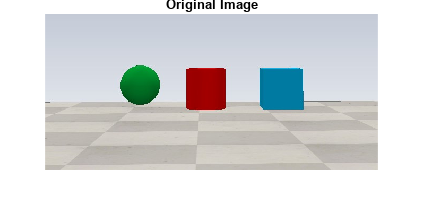

I = imread("ODTestImage.jpeg");
figure;
imshow(I);
title('Original Image')

2) Convert Image to Grayscale

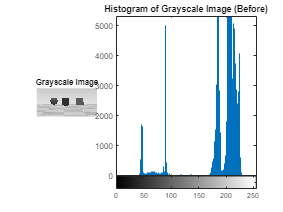

GI = rgb2gray(I);
figure;
subplot(1,3,1)
imshow(GI);
title('Grayscale Image')
subplot(1,3,2:3)
imhist(GI)
title('Histogram of Grayscale Image (Before)')

3) Histogram Equalisation

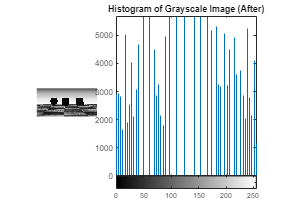

HE = histeq(GI);
figure;
subplot(1,3,1);
imshow(HE);
subplot(1,3,2:3)
imhist(HE)
title('Histogram of Grayscale Image (After)')

4) Image Denoising using Average Filter and Median Filter (Normal)

DI1 = filter2(fspecial('average',5),GI)/255

DI1 =     0.2852    0.3802    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753    0.4753
    0.3807    0.5076    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345    0.6345   

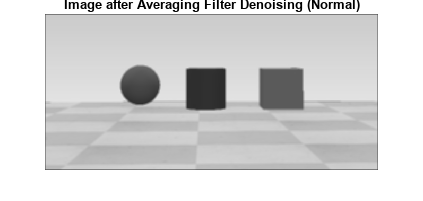

figure, imshow(DI1)
title('Image after Averaging Filter Denoising (Normal)')

DI2 = medfilt2(GI)

DI2 = 294×627 uint8 matrix
     0   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202
   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202
   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202   202
   202   203   203   203   203   203   203   203   203   203   203   2

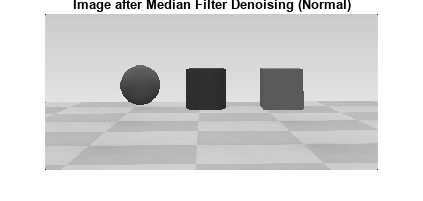

figure, imshow(DI2)
title('Image after Median Filter Denoising (Normal)')

5) Image Denoising using Average Filter and Median Filter (HE)

DI1_HE = filter2(fspecial('average',5),HE)/255

DI1_HE =     0.1256    0.1675    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094    0.2094
    0.1713    0.2284    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855    0.2855

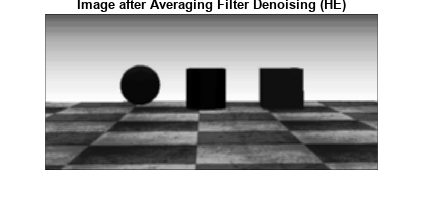

figure, imshow(DI1_HE)
title('Image after Averaging Filter Denoising (HE)')

DI2_HE = medfilt2(HE)

DI2_HE = 294×627 uint8 matrix
     0    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89
    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89
    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89    89
    89    97    97    97    97    97    97    97    97    97    97 

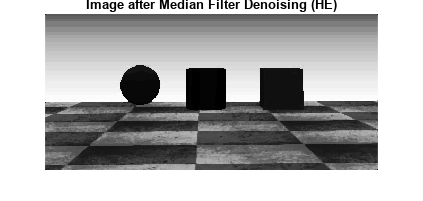

figure, imshow(DI2_HE)
title('Image after Median Filter Denoising (HE)')

6) Edge Detection using Sobel and Canny Filter (Normal)

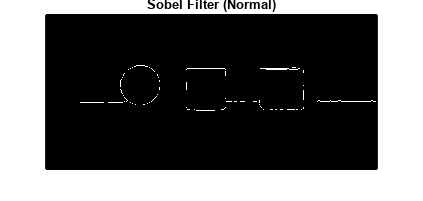

ED1 = edge(DI2,'sobel');
ED2 = edge(DI2,'canny');

figure
imshow(ED1)
title('Sobel Filter (Normal)')

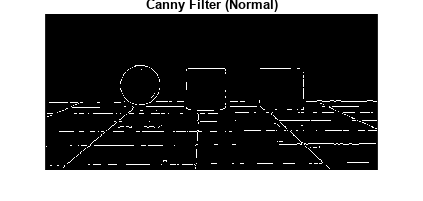


figure
imshow(ED2)
title('Canny Filter (Normal)')

7) Edge Detection using Sobel and Canny Filter (HE)

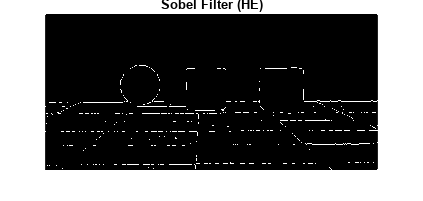

ED1_HE = edge(DI2_HE,'sobel');
ED2_HE = edge(DI2_HE,'canny');

figure
imshow(ED1_HE)
title('Sobel Filter (HE)')

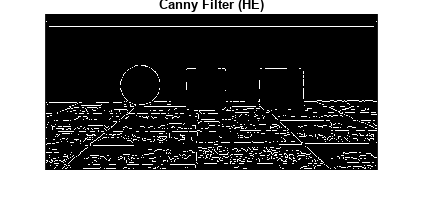


figure
imshow(ED2_HE)
title('Canny Filter (HE)')

8) Image Segementaion using OTSU Thresholding (Normal)

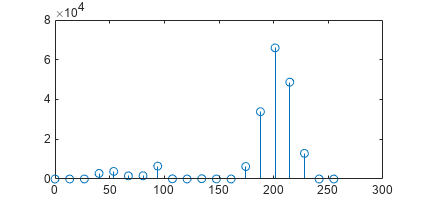

[counts,a] = imhist(DI2,20);
stem(a,counts);

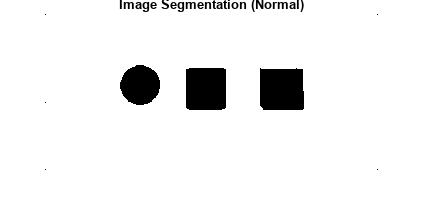

T = otsuthresh(counts);
BI = imbinarize(DI2,T);
figure
imshow(BI);
title('Image Segmentation (Normal)');

9) Image Segementaion using OTSU Thresholding (HE)

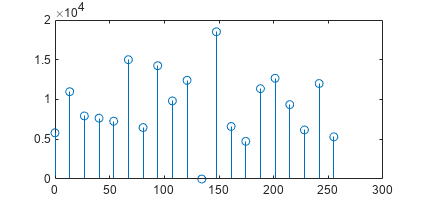

[counts,a] = imhist(DI2_HE,20);
stem(a,counts);

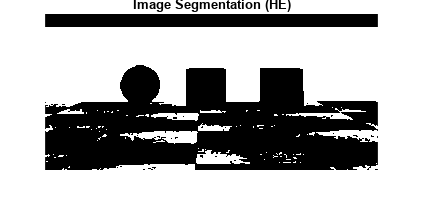

T = otsuthresh(counts);
BI = imbinarize(DI2_HE,T);
figure
imshow(BI);
title('Image Segmentation (HE)')